% Demo_Dynamics_NE_2Link
% 1. 手动推到的NE动力学方程
% 2. 用DH方法+NE程序推导的动力学方程


如图所示，已知两连杆机器人的结构和惯性参数，采用NewtonEular方法推导其动力学方程，最终获得H，C，G三个矩阵。

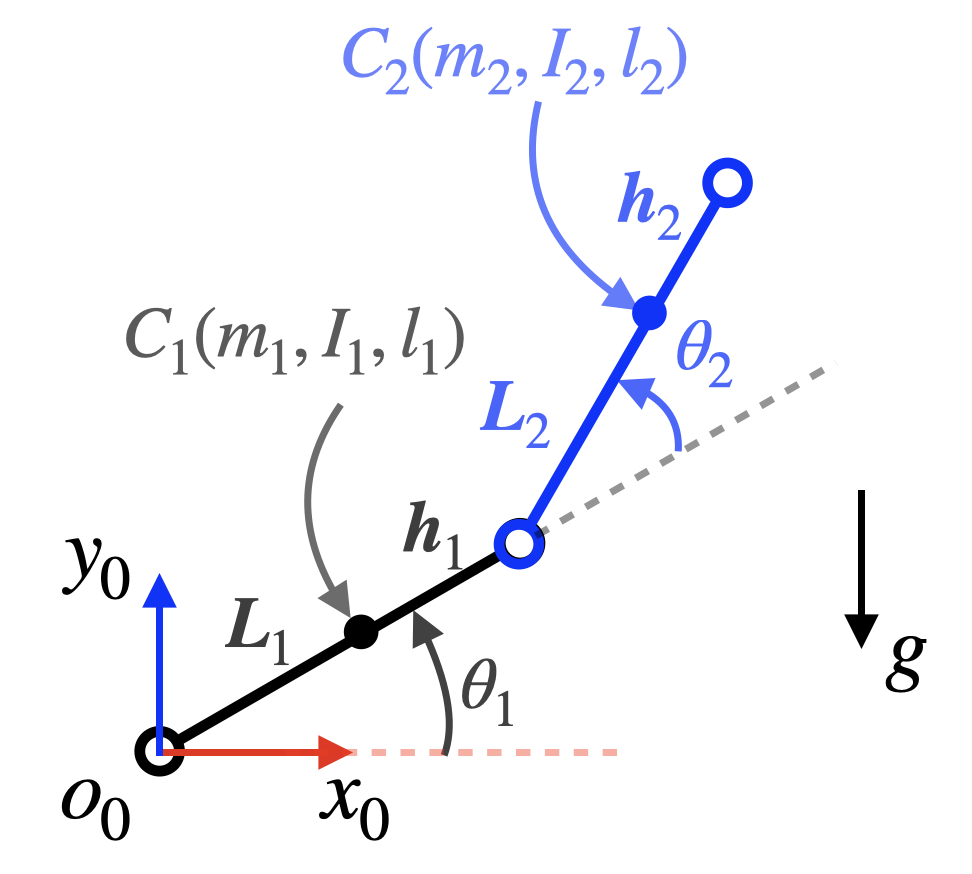，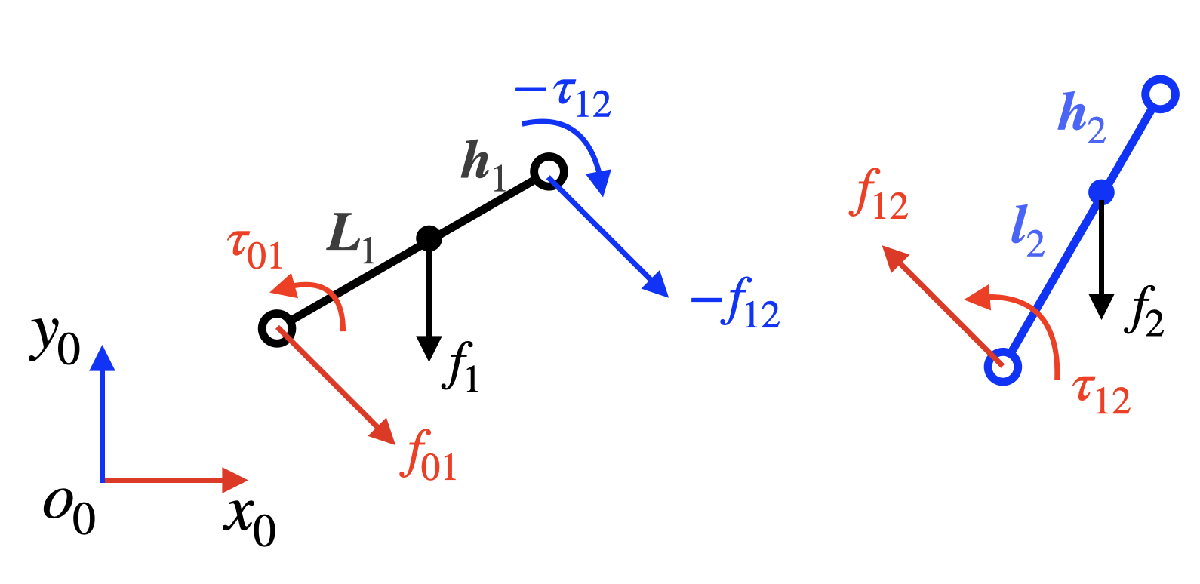

% 用Newton-Eular方法手动推导2连杆机器人的动力学方程

clc
clear
close all

% 定义表示机器人动力学的符号变量
syms m1 m2 
syms I1 I2
syms L1 L2 
syms lc1 lc2 
syms g       
syms theta1 theta1_d theta1_dd 
syms theta2 theta2_d theta2_dd

IC1 = [0 0 0; 0 0 0; 0 0 I1];
IC2 = [0 0 0; 0 0 0; 0 0 I2];

% 动力学推导
% 1. 运动学外推(连杆1～2)
% 1.1 连杆1
theta01 = [0; 0; theta1];
XC01 = rotz(theta01(3)) * [lc1; 0; 0];

VC01    = jacobian(XC01,theta1)*theta1_d    + jacobian(XC01,theta2)*theta2_d;
omega01 = jacobian(theta01,theta1)*theta1_d + jacobian(theta01,theta2)*theta2_d;
AC01 = jacobian(VC01,theta1)*theta1_d           + jacobian(VC01,theta2)*theta2_d ...
     + jacobian(VC01,theta1_d)*theta1_dd        + jacobian(VC01,theta2_d)*theta2_dd;
epsilon01 = jacobian(omega01,theta1)*theta1_dd      + jacobian(omega01,theta2)*theta2_dd ...
          + jacobian(omega01,theta1_d)*theta1_dd    + jacobian(omega01,theta2_d)*theta2_dd;


% 1.2 连杆2
theta02 = theta01 + [0; 0; theta2]; 
XC02 = rotz(theta01(3)) * [L1; 0; 0] + rotz(theta02(3)) * [lc2; 0; 0]; 

VC02 = jacobian(XC02,theta1)*theta1_d + jacobian(XC02,theta2)*theta2_d;
omega02 = jacobian(theta02,theta1)*theta1_d + jacobian(theta02,theta2)*theta2_d;

AC02 = jacobian(VC02,theta1)*theta1_d       + jacobian(VC02,theta2)*theta2_d ...
     + jacobian(VC02,theta1_d)*theta1_dd    + jacobian(VC02,theta2_d)*theta2_dd;
epsilon02 = jacobian(omega02,theta1)*theta1_dd      + jacobian(omega02,theta2)*theta2_dd ...
          + jacobian(omega02,theta1_d)*theta1_dd    + jacobian(omega02,theta2_d)*theta2_dd;

% 2. 动力学内推（连杆2～1）
% 2.1 连杆2
f2 = m2*[0; -g; 0];
f12 = m2*AC02 - f2;

LC12 = rotz(theta02(3)) * [lc2; 0; 0];
tau12 = IC2*epsilon02 - cross(-LC12, f12); % wxwI = 0 here

% 2.2 连杆1
f1 = m1*[0; -g; 0];
f01 = m1*AC01 + f12 - f1;

H1 = rotz(theta01(3)) * [L1-lc1; 0; 0];
tau01 = I1*epsilon01 - cross(-XC01, f01) - cross(H1, -f12) -(-tau12) ; % wxwI = 0 here


% 3 获得动力学方程
% 3.1 关节力矩的表达式
tau = simplify([tau01(3); tau12(3)])

$$tau = \begin{array}{l} \left(\begin{array}{c} I_{1}\,\theta_{1,\mathrm{dd}}+I_{2}\,\theta_{1,\mathrm{dd}}+I_{2}\,\theta_{2,\mathrm{dd}}+{{\mathrm{lc}}_{1}}^{2}\,m_{1}\,\theta_{1,\mathrm{dd}}+\sigma_{3}+\sigma_{2}+{L_{1}}^{2}\,m_{2}\,\theta_{1,\mathrm{dd}}+\sigma_{1}+L_{1}\,g\,m_{2}\,\cos\left(\theta_{1}\right)+g\,{\mathrm{lc}}_{1}\,m_{1}\,\cos\left(\theta_{1}\right)-L_{1}\,{\mathrm{lc}}_{2}\,m_{2}\,{\theta_{2,d}}^{2}\,\sin\left(\theta_{2}\right)+2\,L_{1}\,{\mathrm{lc}}_{2}\,m_{2}\,\theta_{1,\mathrm{dd}}\,\cos\left(\theta_{2}\right)+L_{1}\,{\mathrm{lc}}_{2}\,m_{2}\,\theta_{2,\mathrm{dd}}\,\cos\left(\theta_{2}\right)-2\,L_{1}\,{\mathrm{lc}}_{2}\,m_{2}\,\theta_{1,d}\,\theta_{2,d}\,\sin\left(\theta_{2}\right)\\ I_{2}\,\theta_{1,\mathrm{dd}}+I_{2}\,\theta_{2,\mathrm{dd}}+\sigma_{3}+\sigma_{2}+\sigma_{1}+L_{1}\,{\mathrm{lc}}_{2}\,m_{2}\,{\theta_{1,d}}^{2}\,\sin\left(\theta_{2}\right)+L_{1}\,{\mathrm{lc}}_{2}\,m_{2}\,\theta_{1,\mathrm{dd}}\,\cos\left(\theta_{2}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=g\,{\mathrm{lc}}_{2}\,m_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)\\ \sigma_{2}={{\mathrm{lc}}_{2}}^{2}\,m_{2}\,\theta_{2,\mathrm{dd}}\\ \sigma_{3}={{\mathrm{lc}}_{2}}^{2}\,m_{2}\,\theta_{1,\mathrm{dd}} \end{array}$$


% 3.2 和参考书的结果对比
% %参考书上惯量为0，质心位于杆件的末端时，带入特定的I和L1
% tau1 = subs(tau01(3),I1,0);
% tau1 = subs(tau1,I2,0);
% tau1 = subs(tau1,lc1,L1);
% tau1 = subs(tau1,lc2,L2);
% 
% tau2 = subs(tau12(3),I1,0);
% tau2 = subs(tau2,I2,0);
% tau2 = subs(tau2,lc1,L1);
% tau2 = subs(tau2,lc2,L2);
%
% tau = simplify([tau1; tau2]);

% 3.3 计算HCQ矩阵
q = [theta1; theta2];
q_d = [theta1_d; theta2_d];
q_dd = [theta1_dd; theta2_dd];

H = simplify(jacobian(tau,q_dd));
C = simplify(jacobian(tau,q_d));
G = simplify(jacobian(tau,g)*g);



% 编写Newton-Eular+MDH构成的动力学推导程序，带入两连杆机器人的参数后，用程序求解，

clc
clear
close all

syms q1 q2 m1 m2 L1 L2 lc1 lc2 Ix1 Iy1 Iz1 Ix2 Iy2 Iz2

% MDH parameters
%            alpha a   d  theta
dh_params = [ 0,   0,  0, q1; 
              0,   L1, 0, q2;  
              0,   L2, 0, 0 ];
         
%               x   y   z
mass_center = [lc1, 0,  0;  
               lc2, 0,  0;  ];

%
mass = [m1,m2];

% 只有主惯性 
inertia_1 = [Ix1, 0,    0;
             0,   Iy1,  0;
             0,   0,    Iz1];
         
inertia_2 = [Ix2,   0,      0;
             0,     Iy2,    0; 
             0,     0,      Iz2];

%
inertia_tensor(:,:,1) = inertia_1;
inertia_tensor(:,:,2) = inertia_2;

% external force，no contact force
%        x   y   z
f_ext = [0,  0,  0;     
         0,  0,  0];     

% 
torque =  NewtonEulerDynamics(dh_params, mass, mass_center, inertia_tensor, f_ext)

$$torque = \left(\begin{array}{c} {\mathrm{Iz}}_{1}\,{\mathrm{ddq}}_{1}+{\mathrm{Iz}}_{2}\,{\mathrm{ddq}}_{1}+{\mathrm{Iz}}_{2}\,{\mathrm{ddq}}_{2}+{L_{1}}^{2}\,{\mathrm{ddq}}_{1}\,m_{2}+{\mathrm{ddq}}_{1}\,{{\mathrm{lc}}_{1}}^{2}\,m_{1}+{\mathrm{ddq}}_{1}\,{{\mathrm{lc}}_{2}}^{2}\,m_{2}+{\mathrm{ddq}}_{2}\,{{\mathrm{lc}}_{2}}^{2}\,m_{2}-g\,{\mathrm{lc}}_{2}\,m_{2}\,\cos\left(q_{1}+q_{2}\right)-L_{1}\,g\,m_{2}\,\cos\left(q_{1}\right)-g\,{\mathrm{lc}}_{1}\,m_{1}\,\cos\left(q_{1}\right)-L_{1}\,{{\mathrm{dq}}_{2}}^{2}\,{\mathrm{lc}}_{2}\,m_{2}\,\sin\left(q_{2}\right)+2\,L_{1}\,{\mathrm{ddq}}_{1}\,{\mathrm{lc}}_{2}\,m_{2}\,\cos\left(q_{2}\right)+L_{1}\,{\mathrm{ddq}}_{2}\,{\mathrm{lc}}_{2}\,m_{2}\,\cos\left(q_{2}\right)-2\,L_{1}\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,{\mathrm{lc}}_{2}\,m_{2}\,\sin\left(q_{2}\right)\\ {\mathrm{Iz}}_{2}\,\left({\mathrm{ddq}}_{1}+{\mathrm{ddq}}_{2}\right)+{\mathrm{lc}}_{2}\,m_{2}\,\left(\cos\left(q_{2}\right)\,\left(L_{1}\,{\mathrm{ddq}}_{1}-g\,\cos\left(q_{1}\right)\right)+\sin\left(q_{2}\right)\,\left(L_{1}\,{{\mathrm{dq}}_{1}}^{2}+g\,\sin\left(q_{1}\right)\right)+{\mathrm{lc}}_{2}\,\left({\mathrm{ddq}}_{1}+{\mathrm{ddq}}_{2}\right)\right) \end{array}\right)$$

function torque_list = NewtonEulerDynamics(dh_list, mass_list, mass_center_list, inertia_tensor_list, f_external)
%function torque_list = NED_MDH(dh_list, mass_list, mass_center_list, inertia_tensor_list, f_external)

% 输入参数：
% dh_list：机器人MDH参数
% mass_list: 连杆的质量，单位kg
% mass_center_list：连杆质心在连杆坐标系下的位置，单位：m
% inertia_tensor_list：连杆关于质心坐标系的惯性张量，质心坐标系与连杆坐标系方位一致
% f_external：施加在末端连杆的外力和外力矩

% 输出参数：
% torque_list：用q,dq,ddq（关节位置、速度、加速度）表达的关节力矩
% 重力加速度符号
syms g real

[rows, columns] = size(dh_list);
number_of_links = rows - 1;
if columns ~= 4
    error('wrong DH parameters!')
end

T = sym([]);
R = sym([]);
a = sym([]);
d = sym([]);
alpha = sym([]);
theta = sym([]);

% 定义关节位置，速度，加速度符号
for i = 1:rows
    eval(['syms ','q',      num2str(i),';']);
    eval(['syms ','dq',     num2str(i),';']);
    eval(['syms ','ddq',    num2str(i),';']);
    eval(['q(i)=','q',      num2str(i),';']);
    eval(['dq(i)=','dq',    num2str(i),';']);
    eval(['ddq(i)=','ddq',  num2str(i),';']);
end

for i = 1:rows
    dh = dh_list(i,:);

    % MDH
    alpha(i) = dh(1);       
    a(i) = dh(2);
    d(i) = dh(3);           
    theta(i) = dh(4);

    % q
    if i == rows
        q(i) = 0;
    end
    
    % T matrix with MDH paparmeters
    T(:,:,i) = [cos(q(i)),               -sin(q(i)),              0,                   a(i);
                sin(q(i))*cos(alpha(i)), cos(q(i))*cos(alpha(i)), -sin(alpha(i)),      -sin(alpha(i))*d(i);
                sin(q(i))*sin(alpha(i)), cos(q(i))*sin(alpha(i)), cos(alpha(i)),       cos(alpha(i))*d(i);
                0,                       0,                       0,                   1];
    T = T(:,:,i);
    
    % 提取旋转矩阵R并求逆
    R(:,:,i) = simplify(inv(T(1:3,1:3)));

    % 提取位置P
    P(:,:,i) = T(1:3,4:4);
end

% MDH规定关节轴都是z轴方向
z = [0,0,1]';

% +++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
% Newtow-Eular方法
% 外推 --->
for i = 0:number_of_links-1
    % 前一个连杆的角速度、角加速度，加速度
    if i == 0
        wi =  [0, 0, 0]';
        dwi = [0, 0, 0]';
        dvi = [0, -g, 0]';  %沿-y，g=9.8
    else
        wi = w(:,i);
        dwi = dw(:,i);
        dvi = dv(:,i);
    end
    
    % 当前连杆的
    % 角速度、角加速度
    w(:,:,i+1)  = R(:,:,i+1)*wi + dq(i+1)*z;
    dw(:,:,i+1) = R(:,:,i+1)*dwi + cross(R(:,:,i+1)*wi,dq(i+1)*z) + ddq(i+1)*z;

    % 速度、加速度
    dv(:,:,i+1) = R(:,:,i+1)*(cross(dwi,P(:,:,i+1)) + cross(wi,cross(wi, P(:,:,i+1))) + dvi);
    dvc(:,:,i+1) = cross(dw(:,:,i+1), transpose(mass_center_list(i+1,:)))...
                    + cross(w(:,:,i+1), cross(w(:,:,i+1), transpose(mass_center_list(i+1,:))))...
                    + dv(:,:,i+1);
    
    % 牛顿-欧拉公式，并存储到F，N中
    F(:,:,i+1) = mass_list(i+1)*dvc(:,:,i+1);
    N(:,:,i+1) = inertia_tensor_list(:,:,i+1)*dw(:,:,i+1) + cross(w(:,:,i+1),inertia_tensor_list(:,:,i+1)*w(:,:,i+1));
end

% 
f = sym([]);
n = sym([]);


% 内推 <---
for i = number_of_links:-1:1
    % 最后一个连杆的受力
    if i == number_of_links
        f(:,:,i+1) = f_external(1,:)';
        n(:,:,i+1) = f_external(2,:)';
    end

    % 连杆受到的力
    f(:,:,i) = inv(R(:,:,i+1))*f(:,:,i+1) + F(:,:,i);
    f(:,:,i) = simplify(f(:,:,i));
    
    % 连杆受到的力矩
    n(:,:,i) = N(:,:,i) ...
                + R(:,:,i+1)\n(:,:,i+1) ...
                + cross(transpose(mass_center_list(i,:)), F(:,:,i))...
                + cross(P(:,:,i+1),R(:,:,i+1)\f(:,:,i+1));
    n(:,:,i) = simplify(n(:,:,i));
    
    % 投影到轴
    torque_list(i) = dot(n(:,:,i),z);
end

torque_list = torque_list';

% end of this function
end